[target, ref, fs] = recorded_samples();

cutoff = 400;

target = highpass(target, cutoff, fs);
ref = highpass(ref, cutoff, fs);

source_to_ref = 2;

panel_ir = clipped_irs(128, source_to_ref);
panel_ir = highpass(panel_ir, cutoff, fs);

fxlms = FxLMS(ref, target, panel_ir, 256, .9);
fxlms.gpu = false;
[pred_i, mses_i] = fxlms.learn(10);

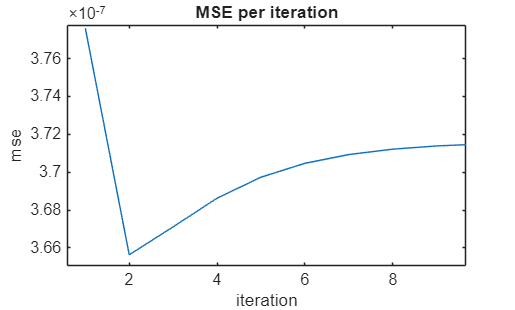

figure
plot(mses_i)
title('MSE per iteration')
xlabel('iteration')
ylabel('mse')

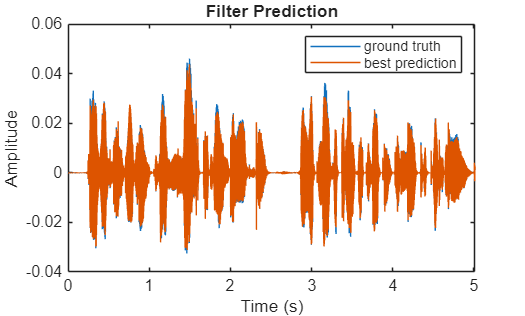

t = (0:length(target) - 1) / fs;
figure
plot(t, target)
hold on
plot(t, pred_i);
legend("ground truth", "best prediction")

title("Filter Prediction")
xlabel("Time (s)")
ylabel("Amplitude")
xlim([t(1), t(end)]);

hold off

save_cancel_clip(-fxlms.ref_filt, 'fxlms_same_session');

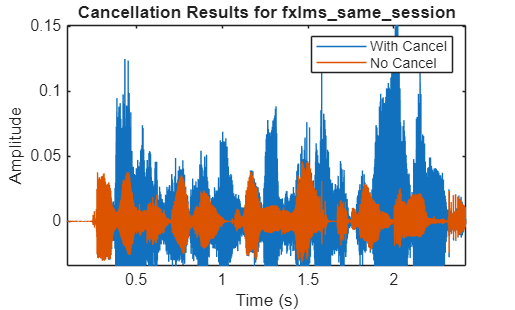

c = CancelAnalysis('fxlms_same_session');
c.plot_cancel_results();